g=graph({'1','1','2','2','2','3','4','4','4','5','6','6','6','7','7','9','9','10','12','13'} ...
       ,{'2','5','3','4','5','4','5','9','7','6','12','13','11','8','9','10','14','11','13','14'})

g =   graph with properties:

    Edges: [20×1 table]
    Nodes: [14×1 table]



% 3 label = 5 node
% 4 label = 3 node
% 5 label = 4 node
% 6 label = 9 node
% 8 label = 6 node
% 9 label = 12 node
% 10 label = 13 node
% 12 label = 8 node
% 13 label = 10 node

p=plot(g)

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '5'  '3'  '4'  '9'  '7'  '6'  '12'  '13'  '11'  '8'  '10'  '14'}
     EdgeLabel: {}
         XData: [1.7816 1.4459 0.8293 1.5743 0.6398 -0.5104 -0.0301 -0.3117 -0.6166 -0.9086 -1.4143 -0.1515 -1.4934 -0.8343]
         YData: [-0.4897 0.2159 -0.4052 0.9671 0.7014 0.6423 1.5920 -1.2317 -2.1650 -1.5019 -0.7641 2.6347 0.2133 -0.4090]
         ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show all properties



n2 = neighbors(g,2)

n2 =      1
     3
     4
     5


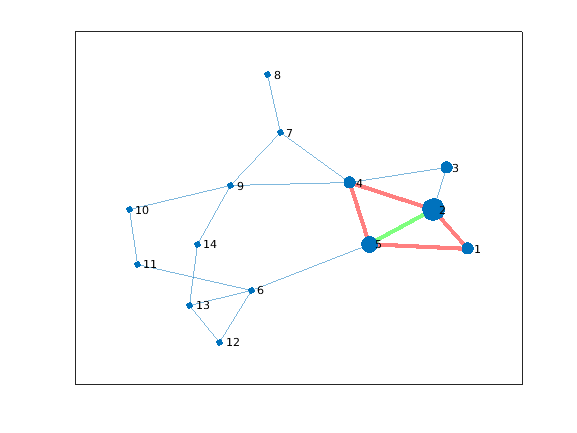

highlight(p,[2 3],'EdgeColor','green')
highlight(p,[2 5 3],'LineWidth',3)
highlight(p,[2 5 3],'EdgeColor','red')
highlight(p,[2 1 3],'LineWidth',3)
highlight(p,[2 1 3],'EdgeColor','red')
highlight(p,[2 3],'LineWidth',3)
highlight(p,n2,'MarkerSize',8)
highlight(p,3,'MarkerSize',12)
highlight(p,2,'MarkerSize',16)




full(adjacency(g)) 

ans =      0     1     1     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     0     0     0     0     0     0     0     0     0
     1     1     0     0     1     0     0     1     0     0     0     0     0     0
     0     1     0     0     1     0     0     0     0     0     0     0     0     0
     0     1     1     1     0     1     1     0     0     0     0     0     0     0
     0     0     0     0     1     0     1     0     0     0     0     0     1     1
     0     0     0     0     1     1     0     0     0     0     0     1     0     0
     0     0     1     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     0     0     0     0     1     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     1     0     0     0     0     1


degree(g)

ans =      2
     4
     4
     2
     5
     4
     3
     4
     2
     3



A=full(adjacency(g));

A =      0     1     1     0     0     0     0     0     0     0     0     0     0     0
     1     0     1     1     1     0     0     0     0     0     0     0     0     0
     1     1     0     0     1     0     0     1     0     0     0     0     0     0
     0     1     0     0     1     0     0     0     0     0     0     0     0     0
     0     1     1     1     0     1     1     0     0     0     0     0     0     0
     0     0     0     0     1     0     1     0     0     0     0     0     1     1
     0     0     0     0     1     1     0     0     0     0     0     1     0     0
     0     0     1     0     0     0     0     0     1     1     1     0     0     0
     0     0     0     0     0     0     0     1     0     1     0     0     0     0
     0     0     0     0     0     0     0     1     1     0     0     0     0     1


p = AllPath(A,6,11);  % function defined in mfile below 

fprintf('--- All paths between source and target ---\n \n');

--- All paths between source and target ---
 


for k=1:size(p,1)
   fprintf('path #%d: %s\n', k, mat2str(p{k}));
end

path #1: [6 5 2 1 3 8 11]
path #2: [6 5 2 3 8 11]
path #3: [6 5 3 8 11]
path #4: [6 5 4 2 1 3 8 11]
path #5: [6 5 4 2 3 8 11]
path #6: [6 7 5 2 1 3 8 11]
path #7: [6 7 5 2 3 8 11]
path #8: [6 7 5 3 8 11]
path #9: [6 7 5 4 2 1 3 8 11]
path #10: [6 7 5 4 2 3 8 11]
path #11: [6 13 11]
path #12: [6 14 10 8 11]
path #13: [6 14 10 9 8 11]



I = 1;
%BB = [];

for k=1:size(p,1)
%%fprintf('path #%d: %s\n',k,mat2str(p{k}));
NOE = numel(p{k});
fprintf('No. of Nodes in path %d: %d\n',k,NOE);

%% The reliability of an N-node route from a source node to a
%% target node is given by: 


$$\prod_{N=1}^N \left(1-\mathrm{fsn}\right)$$


syms x
Rsn = 1-0.1;
reliability = vpa(symprod(Rsn, x, 1, NOE))
BB(I) = reliability;
BB2(I) = -log(reliability);
LATENCY = ((0.1.*(NOE+1)+(2*(0.3.*(NOE-1)))));
I=I+1;
end

No. of Nodes in path 1: 7


$$reliability = 0.4782969$$

No. of Nodes in path 2: 6


$$reliability = 0.531441$$

No. of Nodes in path 3: 5


$$reliability = 0.59049$$

No. of Nodes in path 4: 8


$$reliability = 0.43046721$$

No. of Nodes in path 5: 7


$$reliability = 0.4782969$$

No. of Nodes in path 6: 8


$$reliability = 0.43046721$$

No. of Nodes in path 7: 7


$$reliability = 0.4782969$$

No. of Nodes in path 8: 6


$$reliability = 0.531441$$

No. of Nodes in path 9: 9


$$reliability = 0.387420489$$

No. of Nodes in path 10: 8


$$reliability = 0.43046721$$

No. of Nodes in path 11: 3


$$reliability = 0.729$$

No. of Nodes in path 12: 5


$$reliability = 0.59049$$

No. of Nodes in path 13: 6


$$reliability = 0.531441$$





NOP = numel(p);
%%display(BB)
%%display(BB2)
S = sum(BB2,'all');
SS = 1/S;

SRI = 1/13.*symsum(SS,x,1,NOP)

$$SRI = 0.11166143036505768265894038454691$$

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [13×1 table]


--- Removing Node 1 ---

--- All paths between source and target ---
 


path #1: [6 11]


SRI OF SYS AFTER REMOVING NODE 1: = 0.0091261745971441375250095506600838

G =   graph with properties:

    Edges: [16×1 table]
    Nodes: [13×1 table]


--- Removing Node 2 ---

--- All paths between source and target ---
 


path #1: [6 11]


SRI OF SYS AFTER REMOVING NODE 2: = 0.0091261745971441375250095506600838

G =   graph with properties:

    Edges: [16×1 table]
    Nodes: [13×1 table]


--- Removing Node 3 ---

--- All paths between source and target ---
 


path #1: [6 11]


SRI OF SYS AFTER REMOVING NODE 3: = 0.0091261745971441375250095506600838

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [13×1 table]


--- Removing Node 4 ---

--- All paths between source and target ---
 


path #1: [6 11]


SRI OF SYS AFTER REMOVING NODE 4: = 0.0091261745971441375250095506600838

G =   graph with properties:

    Edges: [15×1 table]
    Nodes: [13×1 table]


--- Removing Node 5 ---

--- All paths between source and target ---
 


path #1: [6 11]


SRI OF SYS AFTER REMOVING NODE 5: = 0.0091261745971441375250095506600838

G =   graph with properties:

    Edges: [16×1 table]
    Nodes: [13×1 table]


--- Removing Node 6 ---

--- All paths between source and target ---
 


path #1: [6 11]


SRI OF SYS AFTER REMOVING NODE 6: = 0.0091261745971441375250095506600838

G =   graph with properties:

    Edges: [17×1 table]
    Nodes: [13×1 table]


--- Removing Node 7 ---

--- All paths between source and target ---
 


SRI OF SYS AFTER REMOVING NODE 7: = 0

G =   graph with properties:

    Edges: [16×1 table]
    Nodes: [13×1 table]


--- Removing Node 8 ---

--- All paths between source and target ---
 


path #1: [6 5 7 11]
path #2: [6 7 11]


SRI OF SYS AFTER REMOVING NODE 8: = 0.01848339158915268359495605196979

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [13×1 table]


--- Removing Node 9 ---

--- All paths between source and target ---
 


path #1: [6 5 7 11]
path #2: [6 7 11]
path #3: [6 12 10 8 3 1 2 4 5 7 11]
path #4: [6 12 10 8 3 1 2 5 7 11]
path #5: [6 12 10 8 3 2 4 5 7 11]
path #6: [6 12 10 8 3 2 5 7 11]
path #7: [6 12 10 8 3 5 7 11]
path #8: [6 13 9 8 3 1 2 4 5 7 11]
path #9: [6 13 9 8 3 1 2 5 7 11]
path #10: [6 13 9 8 3 2 4 5 7 11]
path #11: [6 13 9 8 3 2 5 7 11]
path #12: [6 13 9 8 3 5 7 11]


SRI OF SYS AFTER REMOVING NODE 9: = 0.080377317552829101137698794804408

G =   graph with properties:

    Edges: [17×1 table]
    Nodes: [13×1 table]


--- Removing Node 10 ---

--- All paths between source and target ---
 


path #1: [6 5 7 11]
path #2: [6 7 11]
path #3: [6 12 10 8 3 1 2 4 5 7 11]
path #4: [6 12 10 8 3 1 2 5 7 11]
path #5: [6 12 10 8 3 2 4 5 7 11]
path #6: [6 12 10 8 3 2 5 7 11]
path #7: [6 12 10 8 3 5 7 11]


SRI OF SYS AFTER REMOVING NODE 10: = 0.046886768572483642330324296969238

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [13×1 table]


--- Removing Node 11 ---

--- All paths between source and target ---
 


path #1: [6 5 7 11]
path #2: [6 7 11]
path #3: [6 13 10 8 3 1 2 4 5 7 11]
path #4: [6 13 10 8 3 1 2 5 7 11]
path #5: [6 13 10 8 3 2 4 5 7 11]
path #6: [6 13 10 8 3 2 5 7 11]
path #7: [6 13 10 8 3 5 7 11]
path #8: [6 13 10 9 8 3 1 2 4 5 7 11]
path #9: [6 13 10 9 8 3 1 2 5 7 11]
path #10: [6 13 10 9 8 3 2 4 5 7 11]
path #11: [6 13 10 9 8 3 2 5 7 11]
path #12: [6 13 10 9 8 3 5 7 11]


SRI OF SYS AFTER REMOVING NODE 11: = 0.076851996607529579157975163453338

G =   graph with properties:

    Edges: [19×1 table]
    Nodes: [13×1 table]


--- Removing Node 12 ---

--- All paths between source and target ---
 


path #1: [6 5 2 1 3 8 11]
path #2: [6 5 2 3 8 11]
path #3: [6 5 3 8 11]
path #4: [6 5 4 2 1 3 8 11]
path #5: [6 5 4 2 3 8 11]
path #6: [6 7 5 2 1 3 8 11]
path #7: [6 7 5 2 3 8 11]
path #8: [6 7 5 3 8 11]
path #9: [6 7 5 4 2 1 3 8 11]
path #10: [6 7 5 4 2 3 8 11]
path #11: [6 12 11]
path #12: [6 13 10 8 11]
path #13: [6 13 10 9 8 11]


SRI OF SYS AFTER REMOVING NODE 12: = 0.11166143036505768265894038454691

G =   graph with properties:

    Edges: [18×1 table]
    Nodes: [13×1 table]


--- Removing Node 13 ---

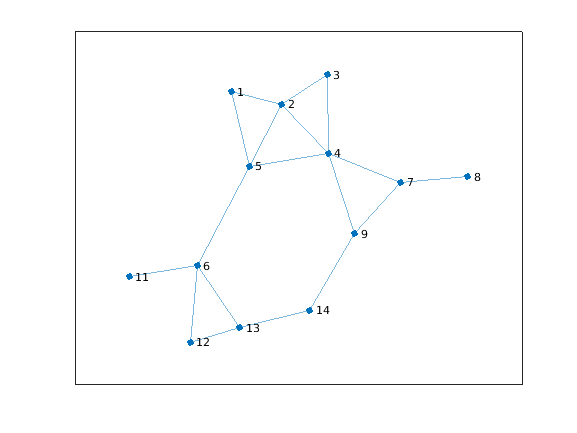

--- All paths between source and target ---
 


path #1: [6 5 2 1 3 8 11]
path #2: [6 5 2 3 8 11]
path #3: [6 5 3 8 11]
path #4: [6 5 4 2 1 3 8 11]
path #5: [6 5 4 2 3 8 11]
path #6: [6 7 5 2 1 3 8 11]
path #7: [6 7 5 2 3 8 11]
path #8: [6 7 5 3 8 11]
path #9: [6 7 5 4 2 1 3 8 11]
path #10: [6 7 5 4 2 3 8 11]
path #11: [6 13 10 8 11]
path #12: [6 13 10 9 8 11]


SRI OF SYS AFTER REMOVING NODE 13: = 0.099558268332481500272831461746369

%%%%%% SRDW CALCULATION %%%%%%%%%%%%

AA = [];
Z = 1;
for W=1:size(p,1)
G = rmnode(g,W)
p = AllPath(full(adjacency(G)),6,11);  % function defined in mfile below 
fprintf('--- Removing Node %d ---',W);
plot(G)
fprintf('--- All paths between source and target ---\n \n');
for k=1:size(p,1)
   fprintf('path #%d: %s\n', k, mat2str(p{k}));
end
I = 1;
%BB = [];

for k=1:size(p,1)
NOE = numel(p{k});
%%fprintf('No. of Nodes encountered in path %d: %d\n',k,NOE);

%% The reliability of an N-node route from a source node to a
%% target node is given by:
syms x
Rsn = 1-0.1;
reliability = vpa(symprod(Rsn, x, 1, NOE));
BB2(I) = -log(reliability);
LATENCY = ((0.1.*(NOE+1)+(2*(0.3.*(NOE-1)))));
I=I+1;
end

NOP = numel(p);
S = sum(BB2,'all');
SS = 1/S;

SRI1f = vpa(1/13.*symsum(SS,x,1,NOP));
CSRDW = (SRI-SRI1f)/SRI;
AA(Z) = CSRDW;
fprintf('SRI OF SYS AFTER REMOVING NODE %d: = %s',W,SRI1f)
Z = Z+1;
end


display(BB2)

$$BB2 = \left(\begin{array}{ccccccccccccc} 0.73752360960478410859250686587519 & 0.63216309394695780736500588503588 & 0.52680257828913150613750490419656 & 0.8428841252626104098200078467145 & 0.73752360960478410859250686587519 & 0.8428841252626104098200078467145 & 0.73752360960478410859250686587519 & 0.63216309394695780736500588503588 & 0.94824464092043671104750882755382 & 0.8428841252626104098200078467145 & 0.52680257828913150613750490419656 & 0.63216309394695780736500588503588 & 0.63216309394695780736500588503588 \end{array}\right)$$

display(AA)

AA =     0.9183    0.9183    0.9183    0.9183    0.9183    0.9183    1.0000    0.8345    0.2802    0.5801    0.3117         0    0.1084


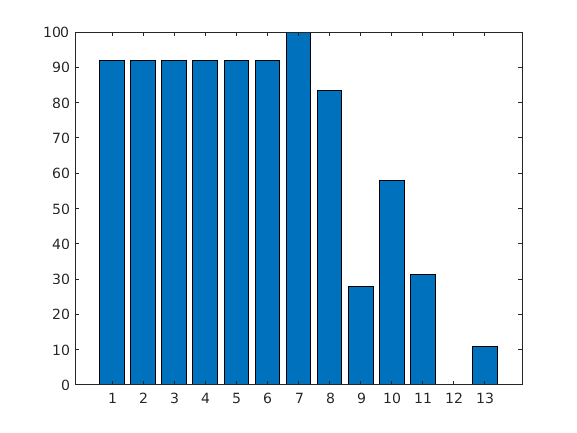

bar(100*AA)

%%%%%% ---------- %%%%%%%%%%

function p = AllPath(A, s, t)
% Find all paths from node #s to node #t
% INPUTS:
%   A is (n x n) symmetric ajadcent matrix
%   s, t are node number, in (1:n)
% OUTPUT
%   p is M x 1 cell array, each contains array of
%   nodes of the path, (it starts with s ends with t)
%   nodes are visited at most once.
if s == t
    p =  {s};
    return
end
p = {};
As = A(:,s)';
As(s) = 0;
neig = find(As);
if isempty(neig)
    return
end
A(:,s) = [];
A(s,:) = [];
neig = neig-(neig>=s);
t = t-(t>=s); 
for n=neig
    p = [p; AllPath(A,n,t)]; %#ok
end
p = cellfun(@(a) [s, a+(a>=s)], p, 'unif', 0);
end %AllPath

%obj=plot(g);
%sd=shortestpath(g,'a','d');
%highlight(obj,sd);
